# LAB 8: FREQUENCY DOMAIN IDENTIFICATION OF QNET DC MOTOR

%---------------------------------------
% Fill in your group number.
GroupNumber = 29;
% Fill in your student Name and ID.
Students(1).Name = 'Patrick Erath';
Students(1).ID = '260719203';
Students(2).Name = 'Ahmed Said';
Students(2).ID = '260665299';
%---------------------------------------

## **0. Objectives**

In this lab, we will use frequency analysis to identify the transfer function of QNET Allied Motion CL40 Series Coreless DC Motor (model 16705).

Follow carefully step 1, 2 and 4 in the guide `QNET DC Motor Quick Start Guide.pdf` to make sure your Qnet DC Motor is setup correctly. You should put the file `QnetDCMotor.m` in the same folder as the livescript. To initiate a connection with the hardware, run the following (You can ignore the warnings, but you shouldn't have any errors)

Motor = QnetDCMotor('port','dev2');

Undefined function 'QnetDCMotor' for input arguments of type 'char'.

## **1. Frequency Response Analysis**

When a cosine wave $x(t) = M_x \cos(\omega t)$ is injected into a linear system, the system will respond with the same frequency $\omega$, a certain magnitude $M_x$ and a certain phase angle relative to the input $\phi$. The steady-state system output can be written as $y(t) = M_y \cos(\omega t + \phi)$.

If $G(j \omega)$ is the frequency response of this system, we define the magnitude and phase at $\omega$ by:


$$M(\omega) = \frac{M_y}{M_x} = || G(j \omega) ||$$



$$\phi(\omega) = \angle G(j \omega)$$


## *1.1 Bode plot*

The Bode plot presents the magnitude and the phase shift between the input and output at each frequency. It is possible to draw a `point-by-point` Bode plot by injecting a cosine wave with a known frequency, once at a time, and measuring the magnitude and phase shift of the output after it reaches its steady-state.

In a bode plot the magnitude is represented in a logarithmic scale in decibels (db).


$$M_{db}(\omega) = 20 \log(M(\omega))$$


The phase at each frequency can be found by measuring the temporal delay between the output and the input when the input is a cosine wave. Another way to measure the phase shift is through the Lissajous method. A Lissajous curve (an ellipsoide) is found when we try to plot the output in function of the input (XY plot). In fact, we can show that at a frequency $\omega$


$$\cos(\phi) = \frac{y^*}{M_y}$$


Where $y^*$ is the value of the output $y$ when the input $x$ is at the maximum $M_x$.

An illustration of using the Lissajous method (taken from Wikipedia) is shown below:

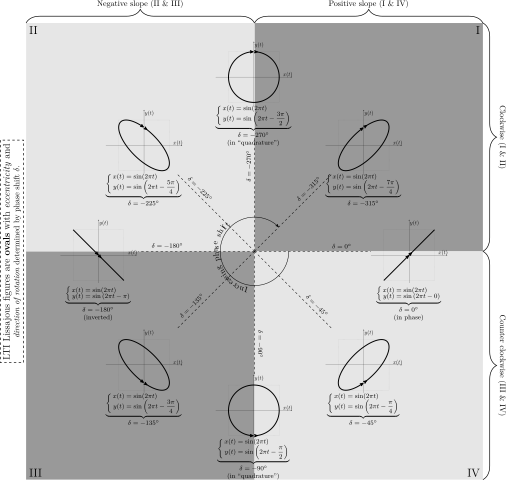

## *Question 1 (2.5 mark)*

- Define the following transfer function in `MATLAB`


$$G(s) = \frac{s + 4}{s^2+s+1}$$


numerator = [1, 4]

numerator =      1     4


denomenator = [1, 1, 1]

denomenator =      1     1     1


G = tf(numerator,denomenator)


G =
 
     s + 4
  -----------
  s^2 + s + 1
 
Continuous-time transfer function.



- Plot the bode graph of this system. (Hint: help `bode`)

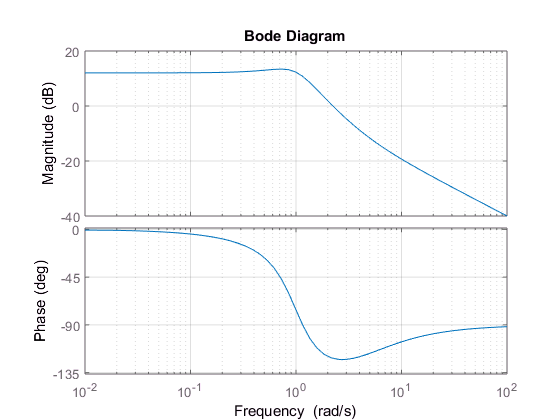

figure(1); clf;
% Plot Bode here
bode(G)
grid on

- Consider the following signal:

rng(datetime('now').Year*GroupNumber)
Freq = round(0.1+rand(1), 2);
t = 0:0.01:round(10/Freq);
x = cos(2*pi*Freq*t);

Using `lsim` simulate the output $y(t)$ representing the response of the system $G$ to the signal $x(t)$.

y = lsim(G, x, t)

Error using DynamicSystem/lsim (line 84)
When simulating the response to a specific input signal, the input data U must be a matrix with as many rows as samples in the time vector T, and as many columns as input channels.


figure(2); clf;
title(sprintf('Group %d - Freq %3.2f Hz - Phase %+03d deg - Magnitude %4.2f',...
    GroupNumber, Freq, round(180*angle(evalfr(G, 2*pi*Freq*1i))/pi), abs(evalfr(G, 2*pi*Freq*1i))));
hold on
plot(t, x)
plot(t, y)
grid on
legend('x', 'y')

- Plot $y(t)$ in function of $x(t)$.

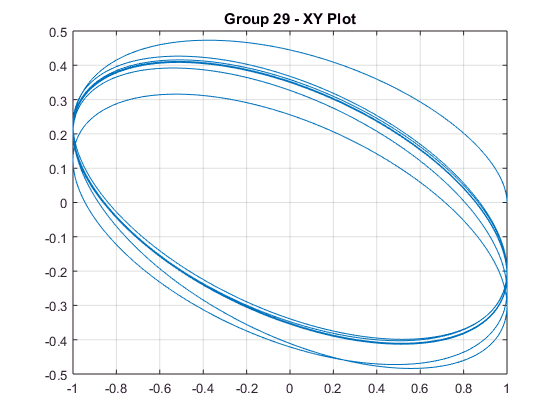

figure(3); clf;
% Plot here
plot(x,y)
title(sprintf('Group %d - XY Plot', GroupNumber));
grid on

- Find graphically the phase $\phi$ and magnitude $M$ at the specified frequency.

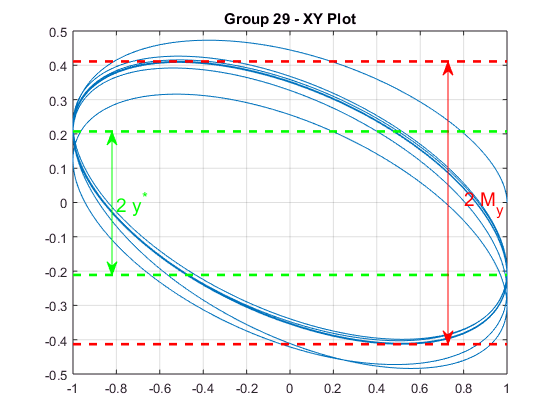

showMyAndYStar(t, x, y, Freq);


% Write phase and magnitude here

phi = 16.42

phi = 16.4200

M = 0.64845

M = 0.6485

## **3. Ident****ification of Qnet DC ****Motor Frequency Response**

To avoid the non-linear domain of the DC Motor at low voltage we will stimulate the DC Motor with offsetted cosine waves. We choose the following voltage signal:


$$v(t) = 4 + 2 \cos(2 \pi f t)$$


To send a cosine wave of frequency $f = 0.5$ Hz to the Qnet DC Motor we do the following

dt = 0.01; % sampling time
T = 15; % simulation duration
t = 0:dt:T; % define the time signal

vAmp = 2; % cosine amplitude
vOffset = 4; % voltage offset

Freq = 0.5; % frequency of cosine wave

Motor.reset;

Undefined variable "Motor" or class "Motor.reset".

Motor.input(vOffset + vAmp * cos(2*pi*Freq*t));
Motor.off;

Motor.save(Students, 'Lab08.Sinewave');

For frequency analysis we are only interseted at the steady-state response. We can retrieve the resulting angular velocity at steady state by:

delay = 5; % Ignore the first 5 seconds of experiment (transient response)
w = Motor.velocity(t >= delay);
v = Motor.voltage(t >= delay);

The following shows a plot of the temporal response.

figure(4), clf;
subplot(2, 1, 1);
plot(t(t >= delay), v, 'r', 'linewidth', 2.0);
legend('Voltage (V)')
grid on
xlim([delay, T])
title(sprintf('Group %d - Voltage and Angular velocity', GroupNumber));
subplot(2, 1, 2);
plot(t(t >= delay), w, 'b', 'linewidth', 2.0);
legend('Angular velocity (rad/s)')
grid on
xlim([delay, T])

And the following shows the XY plot, and how to find $y^*$, $M_y$ and $M_x$.

w_filter = medfilt1(w, 10, 'truncate'); % we can filter the noise if needed

figure(5), clf; hold on;
title(sprintf('Group %d - Voltage vs Angular velocity', GroupNumber));
plot(v, w_filter, 'k');
grid on
xlabel('Voltage (V)')
ylabel('Angular velocity (rad/s)')

## *Question 3 (3.0 marks)*

Find the magnitude and phase of the transfer function of the Qnet DC Motor for the following frequencies.

FreqVect = [0.05, 0.1, 0.2, 0.4, 0.6, 0.8, 1.0, 1.2, 2.0, 4.0, 6.0];


% choose a frequency from FreqVect
Freq = 6.0

% choose a duration
T = 1
t = 0:dt:T; % A vector containing all time samples

% stimulate DC motor with the cosine wave

vAmp = 2; % cosine amplitude
vOffset = 4; % voltage offset

Motor.reset;
Motor.input(vOffset + vAmp * cos(2*pi*Freq*t));
Motor.off;

% save the results
Motor.save(Students, ['Lab08.Q3.' num2str(Freq, '%3.2fHz')]);

% choose a delay to show results after steady-state is achieved
delay = 5;
v = Motor.voltage(t >= delay);
w = Motor.velocity(t >= delay);
w_filter = medfilt1(w, 10, 'truncate');

% XY Plot
figure(6); clf; set(gcf, 'Visible', 'on');
title(sprintf('Group %d - Voltage vs Angular velocity - Freq %3.2f Hz', GroupNumber, Freq));
% write the plot command here:
plot(v, w_filter, 'k');

grid on
xlabel('Voltage (V)')
ylabel('Angular velocity (rad/s)')

% Save a png of the plot
print(strrep(['XYPlot_Freq', num2str(Freq, '%03.2f'), 'Hz_Duration', num2str(T, '%02.1f'), 's'], '.', '_'), '-dpng');

Measure graphically the phase and magnitude and put it here, the size of MagnitudeDB and PhaseDeg is the same as FreqVect

%0.05, 
MagnitudeDB = [25, 24.98, 24.73, 24.54, 23.52, 22.85, 21.57, 20.57, 18.11, 14.32, 13.23];
PhaseDeg = [0, -5.72, -8.840, -15.98, -25.21, -31.22, -37.61, -39.15, -46.02, -46.88, -35.95];

## *Question 4 (1.0 mark)*

Draw the resulting Bode plot (Magnitude (dB) vs Frequency (Hz)) on a semilog plot and Phase (deg) vs Frequency (Hz) on a semilog plot). (Hint: help `semilogx`)

omega = 2 * pi * FreqVect;
figure(7); clf;
subplot(2, 1, 1)
% Draw magnitude here
semilogx(omega, MagnitudeDB)
subplot(2, 1, 2)
% Draw Phase here
semilogx(omega, PhaseDeg)
grid on

## *Question 5 (1.0 mark)*

From the Bode plot, measure the DC gain.

DC_gain = 18.01

## *Question 6 (1.0 mark)*

From the Bode plot, measure the cut-off frequency (Frequency at which the magnitude drops by a factor of $-20\log_{10}\left(\displaystyle \frac{1}{\sqrt{2}}\right)=-3$ (dB) from the DC gain).

w_cutoff = 8

## *Question 7 (1.5 mark)*

For a first order system the transfer function is expressed by


$$H(s) = \displaystyle \frac{DC_{gain}}{1 + \displaystyle
\frac{s}{\omega_{cutoff}}}$$


- Write the transfer function of the identified DC Motor.

s = tf('s')
H = DC_gain / (1 + (s/w_cutoff))

- Complete the code to superpose the experimental bode plot with the bode plot of the identified transfer function.

H_Freq = squeeze(freqresp(H, omega, 'rad/s'))';


H_MagnitudeDB = -20*log(abs(H_Freq)) % find magnitude in db
H_PhaseDeg = - angle(H_Freq)*180/pi% find phas in degrees

figure(8)
subplot(211)
semilogx(omega, [MagnitudeDB; H_MagnitudeDB])
grid on
subplot(212)
semilogx(omega, [PhaseDeg; H_PhaseDeg])
grid on

- How accurate is the point-by-point bode plot for high frequencies ? Comment on your results.

% The point-by-point bode plot is accurate when working with small frequencies,
% However when working with higher frequencies, it becomes less accurate;
% This is due to the fact that the accuracy is inversly proportional to the
% thickness of the curve. Therefore: as we increase the frequency, the thickness of
% the curve increases, and our accuracy drops.

## **4. Useful Functions**

## *4.1 Customize the XY plot*

function showMyAndYStar(t, x, y, Freq)
max_y = max(y(t > round(5/Freq)));
max_x = max(x(t > round(5/Freq)));
min_y = min(y(t > round(5/Freq)));
min_x = min(x(t > round(5/Freq)));
star_y_1 = mean(y(t > round(5/Freq) & abs(x-max_x) < 0.05));
star_y_2 = mean(y(t > round(5/Freq) & abs(x-min_x) < 0.05));

gcf; hold on; axPos = get(gca, 'Position'); xMinMax = xlim; yMinMax = ylim;
plot([min_x, max_x], [max_y, max_y], '--r', 'linewidth', 2.0)
plot([min_x, max_x], [min_y, min_y], '--r', 'linewidth', 2.0)
annotation('doublearrow', [0.8, 0.8],...
    axPos(2)+(([max_y, min_y] - yMinMax(1)) / (yMinMax(2) - yMinMax(1)))*axPos(4), 'Color', 'red')
text(0.8, 0.0, '2 M_y', 'Color', 'red', 'FontSize', 14)
plot([min_x, max_x], [star_y_1, star_y_1], '--g', 'linewidth', 2.0)
plot([min_x, max_x], [star_y_2, star_y_2], '--g', 'linewidth', 2.0)
annotation('doublearrow', [0.2, 0.2],...
    axPos(2)+(([star_y_1, star_y_2] - yMinMax(1)) / (yMinMax(2) - yMinMax(1)))*axPos(4), 'Color', 'green')
text(-0.8, 0.0, '2 y^*', 'Color', 'green', 'FontSize', 14)
end